folderPath = 'C:\Users\vithj\OneDrive\Documents\Visual Studio Code\AI ML\cw-data-cat\U03'; 

if ~isfolder(folderPath)
    error('The specified folder does not exist: %s', folderPath);
end

fileList = dir(fullfile(folderPath, '*.mat'));  

if isempty(fileList)
    error('No .mat files found in the specified folder: %s', folderPath);
end

fileNames = {fileList.name};  
nFiles = numel(fileNames);    

disp('List of .mat files found for User 01:');

List of .mat files found for User 01:


disp(fileNames);

    {'U03_Acc_FreqD_FDay.mat'}    {'U03_Acc_FreqD_MDay.mat'}    {'U03_Acc_TimeD_FDay.mat'}    {'U03_Acc_TimeD_FreqD_FDay.mat'}    {'U03_Acc_TimeD_FreqD_MDay.mat'}    {'U03_Acc_TimeD_MDay.mat'}



Processing file: U03_Acc_FreqD_FDay.mat


Fields in the current file:


    {'Acc_FD_Feat_Vec'}



Analyzing field: Acc_FD_Feat_Vec


Minimum value: 0.000002


Maximum value: 0.997830


Mean value: 0.177723


Standard deviation: 0.307050


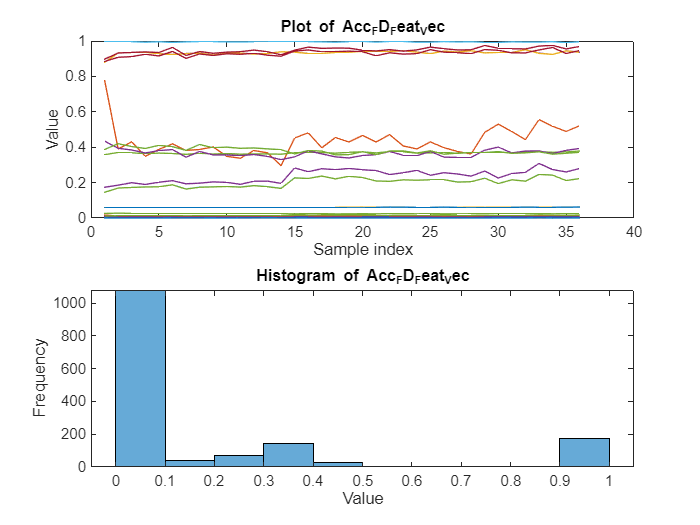

Processing file: U03_Acc_FreqD_MDay.mat


Fields in the current file:


    {'Acc_FD_Feat_Vec'}



Analyzing field: Acc_FD_Feat_Vec


Minimum value: 0.000000


Maximum value: 0.995624


Mean value: 0.173157


Standard deviation: 0.300267


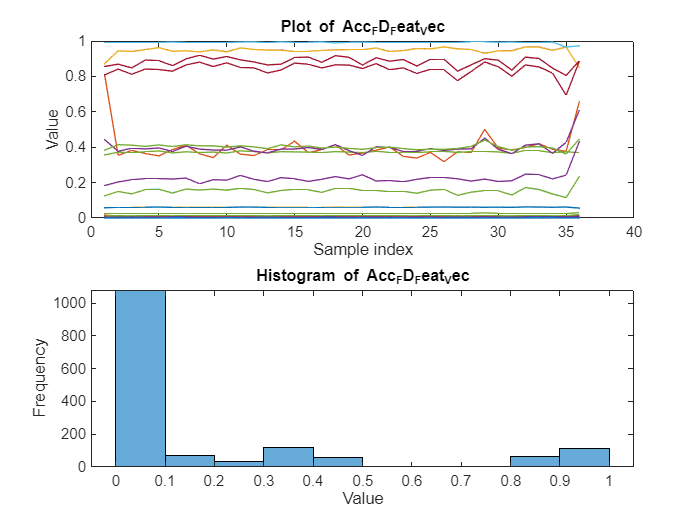

Processing file: U03_Acc_TimeD_FDay.mat


Fields in the current file:


    {'Acc_TD_Feat_Vec'}



Analyzing field: Acc_TD_Feat_Vec


Minimum value: -0.717607


Maximum value: 261.000000


Mean value: 11.940605


Standard deviation: 33.268324


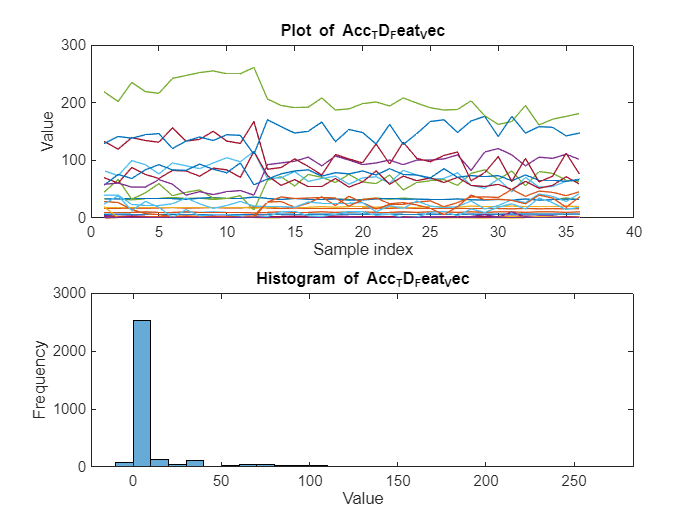

Processing file: U03_Acc_TimeD_FreqD_FDay.mat


Fields in the current file:


    {'Acc_TDFD_Feat_Vec'}



Analyzing field: Acc_TDFD_Feat_Vec


Minimum value: -0.717607


Maximum value: 261.000000


Mean value: 8.079506


Standard deviation: 27.820076


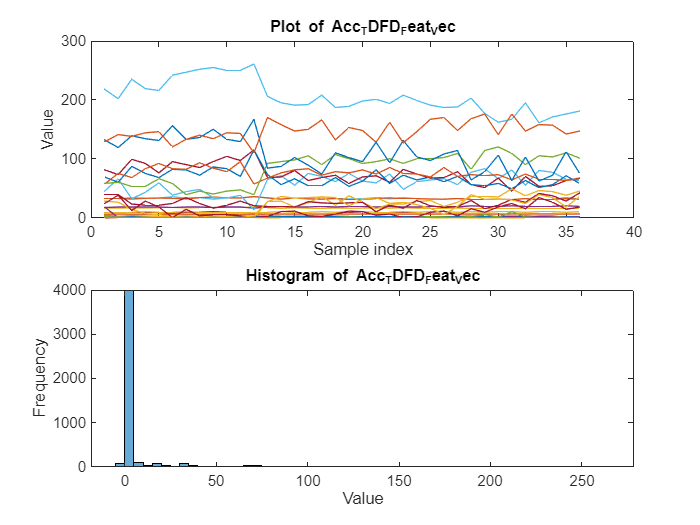

Processing file: U03_Acc_TimeD_FreqD_MDay.mat


Fields in the current file:


    {'Acc_TDFD_Feat_Vec'}



Analyzing field: Acc_TDFD_Feat_Vec


Minimum value: -0.666544


Maximum value: 236.000000


Mean value: 8.079921


Standard deviation: 26.939773


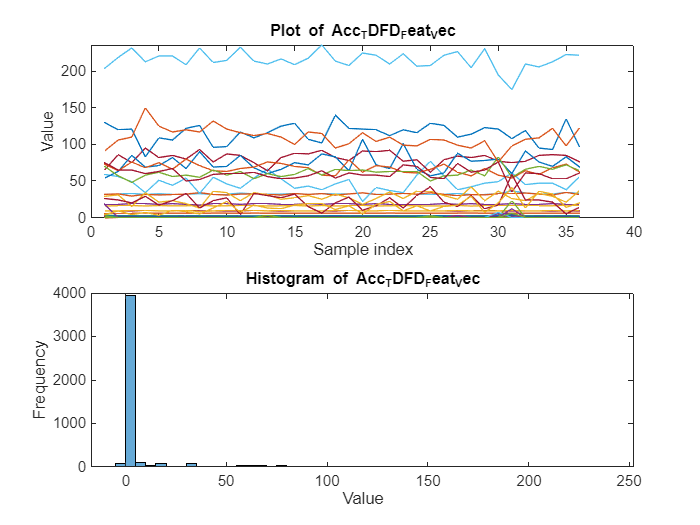

Processing file: U03_Acc_TimeD_MDay.mat


Fields in the current file:


    {'Acc_TD_Feat_Vec'}



Analyzing field: Acc_TD_Feat_Vec


Minimum value: -0.666544


Maximum value: 236.000000


Mean value: 11.943454


Standard deviation: 32.170772


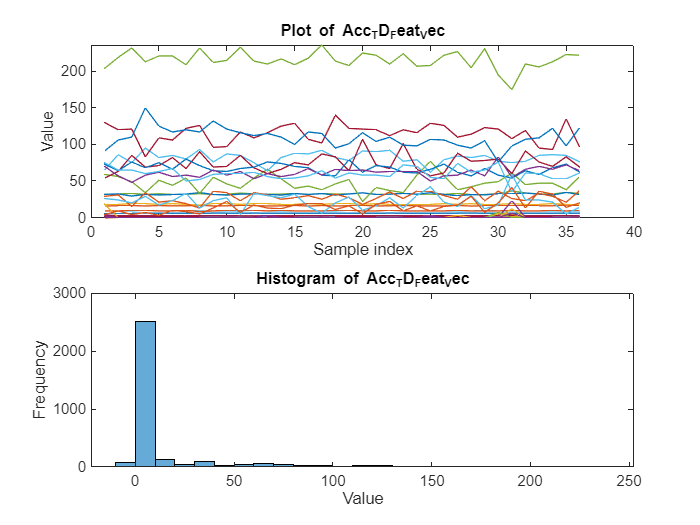


for i = 1:nFiles
    filePath = fullfile(folderPath, fileNames{i});
    
    if exist(filePath, 'file') == 2
        data = load(filePath);  
        fprintf('Processing file: %s\n', fileNames{i});
        
        fields = fieldnames(data);  
        
        disp('Fields in the current file:');
        disp(fields);
       
        for j = 1:length(fields)
            fieldData = data.(fields{j}); 
            
            fprintf('Analyzing field: %s\n', fields{j});
            fprintf('Minimum value: %f\n', min(fieldData(:)));
            fprintf('Maximum value: %f\n', max(fieldData(:)));
            fprintf('Mean value: %f\n', mean(fieldData(:)));
            fprintf('Standard deviation: %f\n', std(fieldData(:)));
            
            figure;  
            subplot(2, 1, 1); 
            plot(fieldData);  
            title(['Plot of ' fields{j}]);
            xlabel('Sample index');
            ylabel('Value');
            
            subplot(2, 1, 2);  
            histogram(fieldData); 
            title(['Histogram of ' fields{j}]);
            xlabel('Value');
            ylabel('Frequency');
        end
    else
        warning('File does not exist: %s', filePath);
    end
end